load('kcs.mat')
%Q1
%a)
pconnection = mean(J,'all')

pconnection = 0.0507

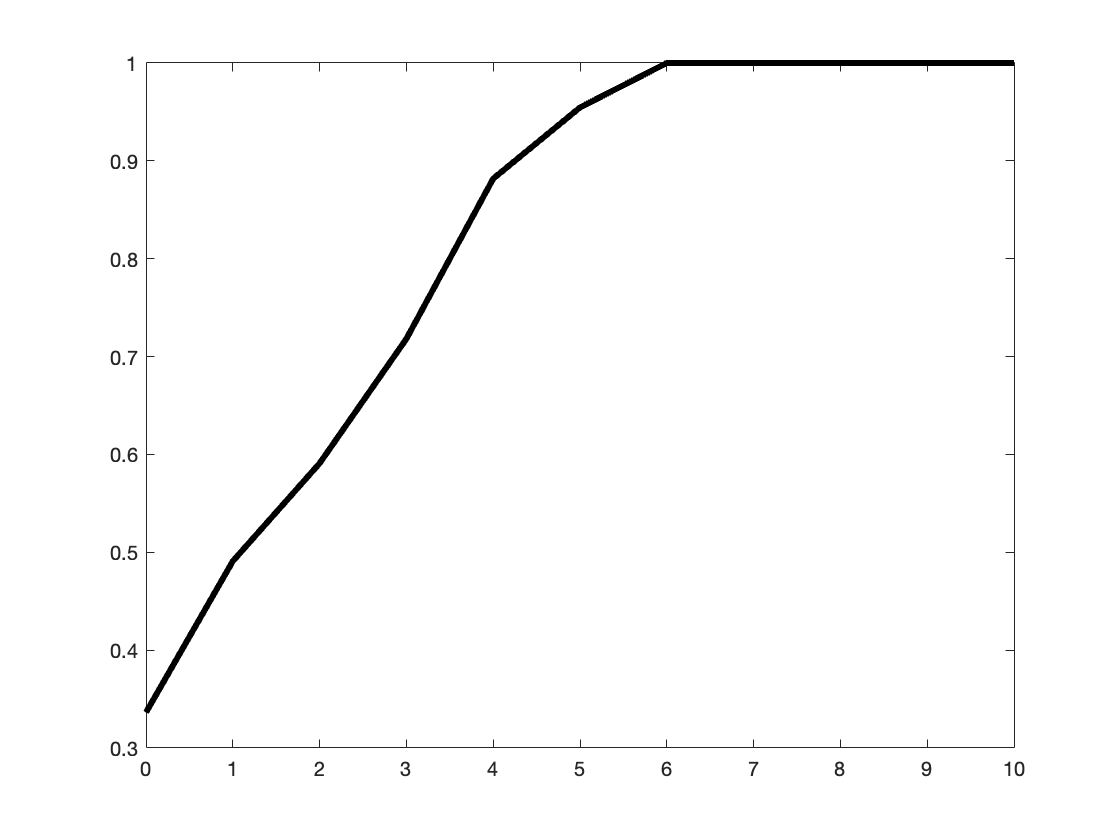

%b)
conns=sum(J,2);
cdf_conns = [];
k = [0:10];
for i = k
    cdf_conns(i+1) = mean(conns<=i);
end
figure
plot(k,cdf_conns,'k','LineWidth',3)

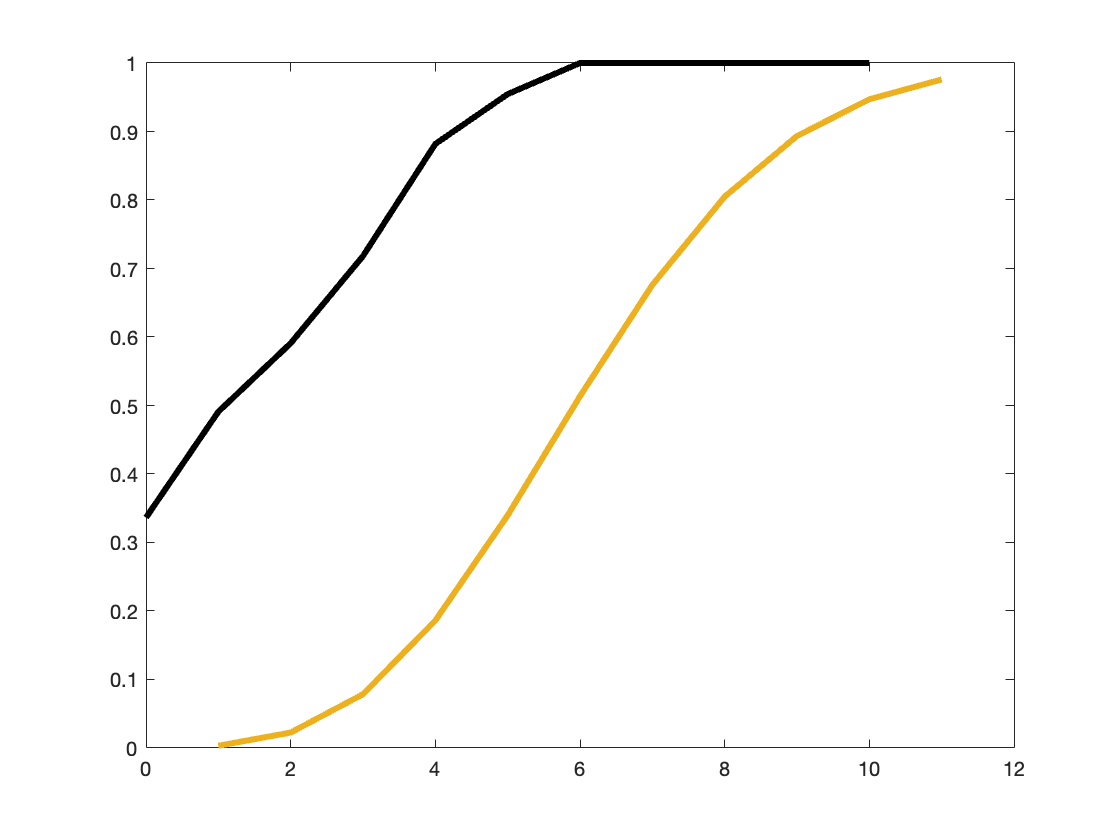

%c)
hold on
binocdf_conns = binocdf(k,length(J),pconnection);
plot(binocdf_conns,'Linewidth',3)

%binomial distribution is not a good model for this data
